%1: load data - ___________________
% Instead of changing directory manually, use the current folder
currentFolder = pwd;

% Search for EDF files in current folder and all subfolders
edfFile = dir(fullfile(currentFolder, '**', '*.edf'));

if isempty(edfFile)
    error('No EDF file found in the current folder or its subfolders.');
end

% Load the first EDF file found
EEG = pop_biosig(fullfile(edfFile(1).folder, edfFile(1).name));

sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel



% Name the dataset based on filename
[~, fname, ~] = fileparts(edfFile(1).name);
EEG.setname = fname;



% Your data as a string
data_string = [
    "name	x	y	z	type	material\n",...
    "Fp1	-32	77	19	cup	Ag/AgCl\n",...
    "Fp2	32	77	19	cup	Ag/AgCl\n",...
    "F3	-52	35	57	cup	Ag/AgCl\n",...
    "F4	52	35	57	cup	Ag/AgCl\n",...
    "C3	-69	-29	69	cup	Ag/AgCl\n",...
    "C4	69	-29	69	cup	Ag/AgCl\n",...
    "P3	-54	-92	44	cup	Ag/AgCl\n",...
    "P4	54	-92	44	cup	Ag/AgCl\n",...
    "O1	-31	-116	-7	cup	Ag/AgCl\n",...
    "O2	31	-116	-7	cup	Ag/AgCl\n",...
    "F7	-72	32	5	cup	Ag/AgCl\n",...
    "F8	72	32	5	cup	Ag/AgCl\n",...
    "T7	-83	-21	-4	cup	Ag/AgCl\n",...
    "T8	83	-21	-4	cup	Ag/AgCl\n",...
    "P7	-73	-74	-8	cup	Ag/AgCl\n",...
    "P8	73	-74	-8	cup	Ag/AgCl\n",...
    "Fz	0	37	84	cup	Ag/AgCl\n",...
    "Cz	0	-34	105	cup	Ag/AgCl\n",...
    "Pz	0	-98	66	cup	Ag/AgCl\n",...
    "F1	-29	37	76	cup	Ag/AgCl\n",...
    "F2	29	37	76	cup	Ag/AgCl\n",...
    "P1	-30	-97	62	cup	Ag/AgCl\n",...
    "P2	30	-97	62	cup	Ag/AgCl\n",...
    "AF3	-37	64	44	cup	Ag/AgCl\n",...
    "AF4	37	64	44	cup	Ag/AgCl\n",...
    "P5	-69	-83	19	cup	Ag/AgCl\n",...
    "P6	69	-83	19	cup	Ag/AgCl\n",...
    "FC5	-77	4	32	cup	Ag/AgCl\n",...
    "FC6	77	4	32	cup	Ag/AgCl\n",...
    "C5	-82	-25	31	cup	Ag/AgCl\n",...
    "C6	82	-25	31	cup	Ag/AgCl\n",...
    "FT7	-79	5	-1	cup	Ag/AgCl\n",...
    "TP7	-84	-49	-6	cup	Ag/AgCl\n",...
    "TP8	84	-49	-6	cup	Ag/AgCl\n",...
    "PO5	-48	-106	8	cup	Ag/AgCl\n",...
    "PO6	49	-105	8	cup	Ag/AgCl\n",...
    "AF7	-57	58	12	cup	Ag/AgCl\n",...
    "AF8	57	58	12	cup	Ag/AgCl\n",...
    "FpZ	0	85	23	cup	Ag/AgCl\n",...
    "FCZ	0	4	99	cup	Ag/AgCl\n",...
    "CPZ	0	-72	94	cup	Ag/AgCl\n",...
    "POZ	0	-115	33	cup	Ag/AgCl\n",...
    "OZ	0	-121	-5	cup	Ag/AgCl\n",...
    "PO3	-36	-111	20	cup	Ag/AgCl\n",...
    "PO4	36	-111	20	cup	Ag/AgCl\n",...
    "CP1	-37	-70	86	cup	Ag/AgCl\n",...
    "CP2	37	-70	86	cup	Ag/AgCl\n",...
    "CP3	-66	-63	61	cup	Ag/AgCl\n",...
    "CP4	66	-63	61	cup	Ag/AgCl\n",...
    "C1	-39	-32	93	cup	Ag/AgCl\n",...
    "C2	39	-32	93	cup	Ag/AgCl\n",...
    "F5	-66	32	32	cup	Ag/AgCl\n",...
    "F6	66	32	31	cup	Ag/AgCl\n",...
    "FT8	79	5	-1	cup	Ag/AgCl\n",...
    "FC3	-62	3	64	cup	Ag/AgCl\n",...
    "FC4	62	3	64	cup	Ag/AgCl\n",...
    "FC1	-35	3	87	cup	Ag/AgCl\n",...
    "FC2	35	3	87	cup	Ag/AgCl\n",...
    "CP5	-80	-55	26	cup	Ag/AgCl\n",...
    "CP6	80	-55	26	cup	Ag/AgCl\n",...
    "PO7	-56	-100	-8	cup	Ag/AgCl\n",...
    "PO8	56	-100	-8	cup	Ag/AgCl"];

% Read the data from the string
lines = splitlines(data_string);  % Split into lines
lines = lines(2:end);             % Remove the header line

% Initialize the struct array
electrode_data = struct();

% Loop through each line and populate the struct
for i = 1:length(lines)
    if isempty(lines{i})
        continue; % Skip empty lines
    end

    values = strsplit(lines{i}, '\t'); % Split by tab delimiter

    electrode_data(i).name = values{1};
    electrode_data(i).x = str2double(values{2});
    electrode_data(i).y = str2double(values{3});
    electrode_data(i).z = str2double(values{4});
    electrode_data(i).type = values{5};
    electrode_data(i).material = values{6};
end

% Remove empty structs, if any
electrode_data = electrode_data(~cellfun('isempty', {electrode_data.name}));

% Define the desired labels for the 62-channel subset
desired_labels = {'Fp1', 'Fp2', 'F3', 'F4', 'C3', 'C4', 'P3', 'P4', 'O1', 'O2', 'F7', 'F8', 'T7', 'T8', 'P7', 'P8', 'Fz', 'Cz', 'Pz', 'F1', 'F2', 'P1', 'P2', 'AF3', 'AF4', 'P5', 'P6', 'FC5', 'FC6', 'C5', 'C6', 'FT7', 'TP7', 'TP8', 'PO5', 'PO6', 'AF7', 'AF8', 'FpZ', 'FCZ', 'CPZ', 'POZ', 'OZ', 'PO3', 'PO4', 'CP1', 'CP2', 'CP3', 'CP4', 'C1', 'C2', 'F5', 'F6', 'FT8', 'FC3', 'FC4', 'FC1', 'FC2', 'CP5', 'CP6', 'PO7', 'PO8'};

% Pre-allocate the final_electrode_data struct array
num_electrodes = length(desired_labels);
final_electrode_data = struct('name', [], 'x', [], 'y', [], 'z', [], 'type', [], 'material', []);
final_electrode_data = repmat(final_electrode_data, 1, num_electrodes);

% Populate the final_electrode_data struct array
for i = 1:num_electrodes
    label = desired_labels{i};
    index = find(strcmp({electrode_data.name}, label));

    if ~isempty(index)
        % Assign the data if the label is found
        final_electrode_data(i) = electrode_data(index);
    else
        % If the label is not found, leave the pre-allocated struct element empty
        disp(['Warning: Label ' label ' not found in the data. Leaving element ' num2str(i) ' empty.']);
        final_electrode_data(i).name = label; % Store the label, but leave other fields empty
    end
end

% Save the struct array to a .mat file
save('electrode_locations.mat', 'final_electrode_data');

disp('Data saved to electrode_locations.mat');

Data saved to electrode_locations.mat



 [final_electrode_data.labels] = final_electrode_data.name; final_electrode_data = orderfields(final_electrode_data,[1:0,7,1:6]); final_electrode_data = rmfield(final_electrode_data,'name');

EEG.chanlocs= final_electrode_data;
EEG=pop_chanedit(EEG, {'lookup','standard_1005.elc'});

readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700 702
65 channel with the same label found and imported
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


%events
edfName = edfFile(1).name;               % e.g. "sub-CBM00008_task-protmap.edf"
[~, baseName, ~] = fileparts(edfName);

% ---
baseName = strrep(baseName, '_eeg', '');

eventsFile = fullfile(edfFile(1).folder, [baseName '_events.tsv']);

if ~isfile(eventsFile)
    error('No events file found for %s', baseName);
end

% Read events
eventTable = readtable(eventsFile, 'FileType','text','Delimiter','\t');
event_struct = table2struct(eventTable);

%event_struct = table2struct(eventTable, 'ToScalar', false);  %NEW MS MOQIMI


% Map "value" -> "type", "sample" -> "latency"
[event_struct.type] = event_struct.value;
event_struct = rmfield(event_struct,'value');
[event_struct.latency] = event_struct.sample;
event_struct = rmfield(event_struct,'sample');




EEG.event = event_struct;

% === Save dataset ===
% Extract subject number (everything between 'sub-CBM' and next '_')
edfName = edfFile(1).name;
subID = regexp(edfName, 'sub-CBM\d+', 'match', 'once');  % e.g. "sub-CBM00002"

% Build descriptive output name
outputFile = [subID '_withEventsLoc.set'];   % e.g. "sub-CBM00002_withEventsLoc.set"
outputPath = edfFile(1).folder;

% Save
EEG = pop_saveset(EEG, 'filename', outputFile, 'filepath', outputPath);

Saving dataset...


pop_eegfiltnew() - performing 661 point highpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): 1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.5 Hz


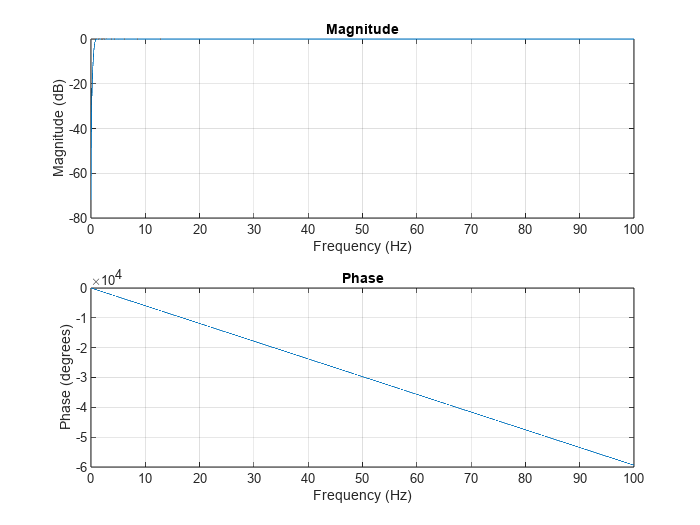

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% ----------------------------- % FILTER AND SAVE
% Extract subject ID from EDF filename
edfName = edfFile(1).name;
subID = regexp(edfName, 'sub-CBM\d+', 'match', 'once');  % e.g. "sub-CBM00002"
outputPath = edfFile(1).folder;  % same folder as EDF

% --- 1 Hz high-pass filter ---
EEG = pop_eegfiltnew(EEG, 'locutoff',1,'plotfreqz',1);

[ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 1



% Save with descriptive name
outputFile1 = [subID '_with1HzFilt.set'];
EEG = pop_saveset(EEG, 'filename', outputFile1, 'filepath', outputPath);

Saving dataset...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 10 Hz
pop_eegfiltnew() - passband edge(s): 40 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 45 Hz


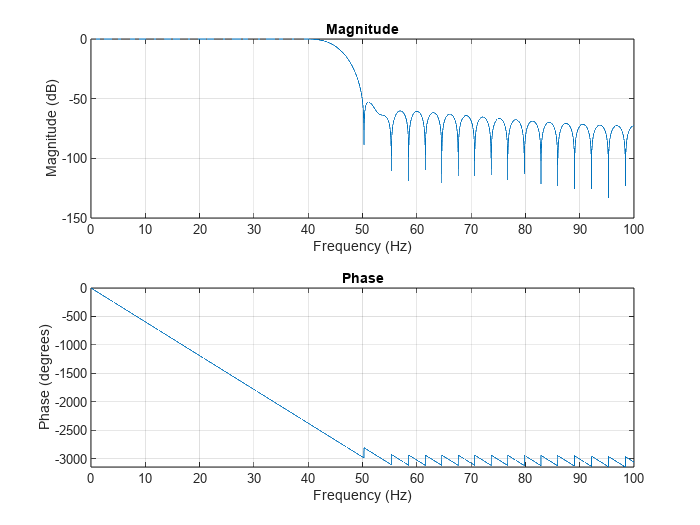

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

% --- 40 Hz low-pass filter ---
EEG = pop_eegfiltnew(EEG, 'hicutoff',40,'plotfreqz',1);

[ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, 2,'gui','off'); 

Creating a new ALLEEG dataset 2



% Save with descriptive name
outputFile2 = [subID '_with1and40HzFilt.set'];
EEG = pop_saveset(EEG, 'filename', outputFile2, 'filepath', outputPath);

Saving dataset...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


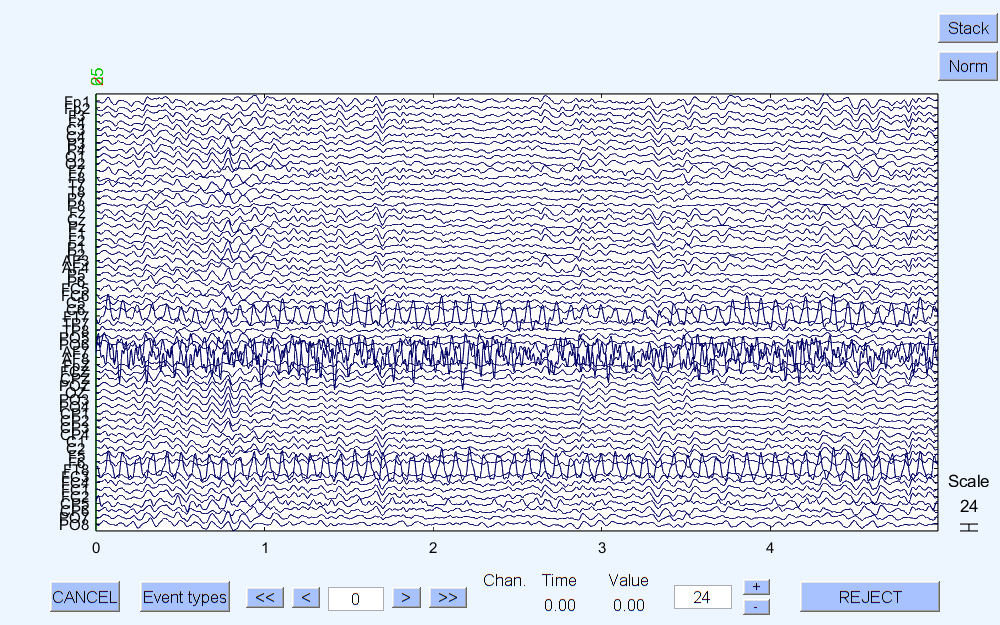

[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

% --- Plot final filtered EEG ---
pop_eegplot(EEG, 1, 1, 1);


%5_________before ICA_______________________________________
% Launch EEGLAB
% ----------------------------- % BEFORE ICA
% Launch EEGLAB
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\shab\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ARfitStudio" v0.41 (see >> help eegplugin_arfitStudio)
EEGLAB: adding "Biosig" v3.8.4 to the path
EEGLAB: adding "ERPLAB" v12.00 (see >> help eegplugin_erplab) - new version 12.10 available
EEGLAB: adding "FCLAB" v1.0.0 (see >> help eegplugin_fclab)
EEGLAB: adding "Fieldtrip-lite" v20240111 to the path - new version 250523 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel) - new version 1.7 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel) - new version 1.7 available
EEGLAB: adding "MFFMatlabIO" v5.0 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "MST" v1.0 (see >> help eegplugin_microstate)
EEGLAB: adding "SIFT" v1.6 (see >> help eegp


% Use subject ID and folder from EDF file info
edfName   = edfFile(1).name;
subID     = regexp(edfName, 'sub-CBM\d+', 'match', 'once');  % e.g. "sub-CBM00002"
outputPath = edfFile(1).folder;

% Build expected filtered dataset name (from step 4)
inputFile = [subID '_with1and40HzFilt.set'];

% Load dataset
EEG = pop_loadset('filename', inputFile, 'filepath', outputPath);

pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\sub-CBM00281_with1and40HzFilt.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\sub-CBM00281_with1and40HzFilt.fdt'...



% Update channel locations before ICA
EEG.chanlocs = final_electrode_data; 
EEG = pop_chanedit(EEG, 'lookup', 'standard_1005.elc');

readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700 702
62 channel with the same label found and imported
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


EEG = eeg_checkset(EEG);


%___________________________remove bad channels

% (example: 32 37 38 54 62)

% Before removing channels
original_labels = {EEG.chanlocs.labels};

% Bad channels as indices
bad_channels = [32 37 38 54 62];

% Print labels of bad channels
fprintf('Removing bad channels: %s\n', strjoin(original_labels(bad_channels), ', '));

Removing bad channels: FT7, AF7, AF8, FT8, PO8



% Remove bad channels
EEG = pop_select(EEG, 'nochannel', bad_channels);

Removing 5 channel(s)...



% save clean chan
loc57 = EEG.chanlocs;       % this is now 57×1 struct
save('loc57.mat','loc57');
disp('Saved 57‐channel locs to loc57.mat');

Saved 57‐channel locs to loc57.mat



% Get current folder
currentFolder = pwd; 

% Define subject ID (example, you should have this defined already)
% subID = 'sub08';  % <- make sure subID exists as a string

% Define a base filename
baseFilename = [subID, '_no_bad_channels'];

% Create a full filename with .set extension
fullFilename = [baseFilename, '.set'];

% Save the EEG dataset in the current folder
pop_saveset(EEG, 'filename', fullFilename, 'filepath', currentFolder);

Saving dataset...



fprintf('Dataset saved in current folder as: %s\n', fullFilename);

Dataset saved in current folder as: sub-CBM00281_no_bad_channels.set


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


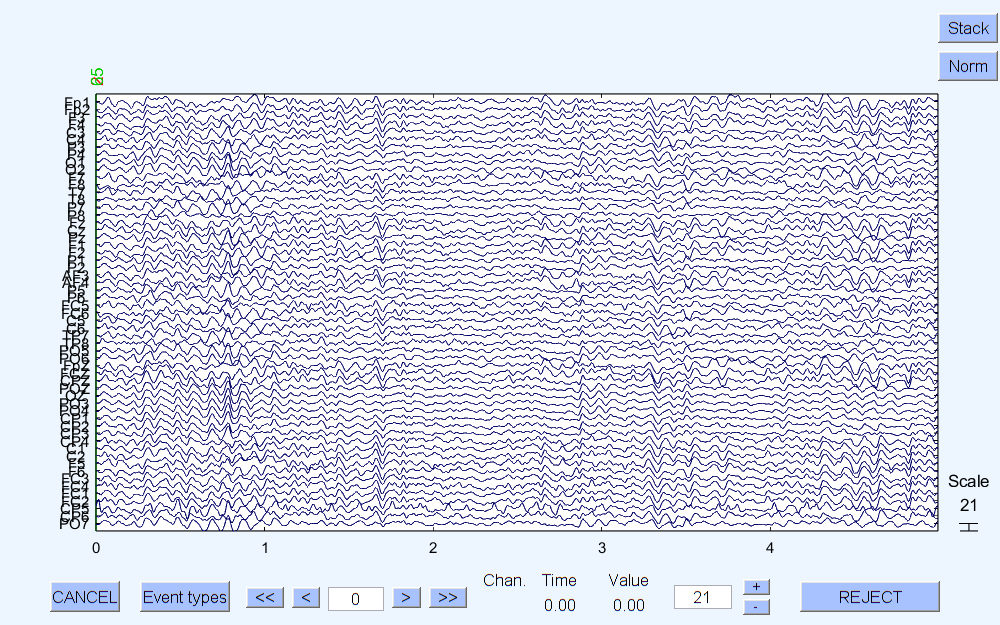


%newwwwwwwwwwwwwwwwwwww----------------------------------------
pop_eegplot(EEG, 1, 1, 1);


% Prompt user to enter bad channels as string (e.g. "32 37 38" or "15")
bad_ch_str = input('Enter bad channel indices separated by space or comma (e.g. 32 37 38): ','s');

if ~isempty(bad_ch_str)
    % Convert string to numeric array
    bad_channels = str2num(bad_ch_str); %#ok<ST2NM>
    
    if ~isempty(bad_channels)
        original_labels = {EEG.chanlocs.labels};
        fprintf('Removing bad channels: %s\n', strjoin(original_labels(bad_channels), ', '));

        % Store current channel locations for interpolation reference
        original_chanlocs = EEG.chanlocs;

        % Remove bad channels
        EEG = pop_select(EEG, 'nochannel', bad_channels);

        % Interpolate missing channels using original channel locations
        EEG = pop_interp(EEG, original_chanlocs, 'spherical');

        % Update and save cleaned channel locations
        loc57 = EEG.chanlocs;       
        save('loc57.mat','loc57');
        disp('Saved cleaned channel locations to loc57.mat');
    else
        disp('No valid channel numbers detected.');
    end
else
    % If user input empty, load previously saved loc57 if exists
    if exist('loc57.mat', 'file')
        load('loc57.mat', 'loc57');
        EEG.chanlocs = loc57;
        disp('No channels removed; loaded previously saved loc57.mat');
    else
        disp('No channels removed, no previously saved loc57.mat file found.');
    end
end

No channels removed; loaded previously saved loc57.mat


% Ensure EEG structure is consistent after changes
EEG = eeg_checkset(EEG);
%newwwwwwwwwwwwwwwwwwww----------------------------------------
pop_eegplot(EEG, 1, 1, 1);



%6_______ICA_______________________________________
%% Run ICA
EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'rndreset','yes','interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [57,220800] = 57 channels, 220800 frames/nFinding 57 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 67 frames per ICA weight ((3249)^2 = 220800 weights, Initial learning rate will be 0.001, block size 62.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -233.724 to 138.55
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lrate 0.001000, wchange 36.76490542, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 3.87774246, angledelta  0.0 deg
Lowering learni

[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Scaling components to RMS microvolt
Creating a new ALLEEG dataset 1


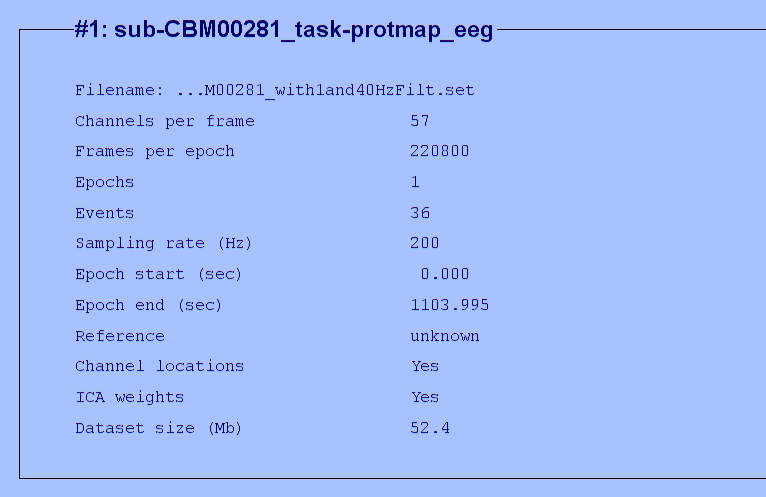

eeglab redraw

%% Save copy before ICA (for later comparison)
EEG_beforeICA = EEG;

%% Run ICLabel to classify components


% ✅ Check ICA fields before running ICLabel
if isempty(EEG.icaweights) || isempty(EEG.icawinv) || isempty(EEG.icachansind)
    error('ICA fields missing. Check ICA computation.');
end

% ✅ DO NOT change chanlocs after ICA
% Run ICLabel immediately
EEG = pop_iclabel(EEG);

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


%7______Identify components with high probability of being muscle, eye, or noise
EEG.etc.ic_classification.ICLabel.classes

ans = 1×7 cell array
    {'Brain'}    {'Muscle'}    {'Eye'}    {'Heart'}    {'Line Noise'}    {'Channel Noise'}    {'Other'}


IC = EEG.etc.ic_classification.ICLabel.classifications;

n_ICs = size(IC, 1);

% Artifact types
muscle_comps = find(IC(:,2) > 0.6);
eye_comps    = find(IC(:,3) > 0.2);
heart_cmps = find(IC(:,4)> 0.6);
lineNoise_comps  = find(IC(:,5) > 0.6);
channelNoise_comps = find(IC(:,6) > 0.6);
other_cmps= find(IC(:,7) > 0.9);
artifact_comps = unique([muscle_comps;heart_cmps; eye_comps; lineNoise_comps; channelNoise_comps; other_cmps]);

% What would remain after artifact removal?
to_keep = setdiff(1:n_ICs, artifact_comps);
brain_prob = IC(:,1);
n_brain = sum(brain_prob(to_keep) > 0.3);
prop_brain = n_brain / n_ICs;

% If less than 30% would be brain after removal...
if prop_brain < 0.3
    % Identify unknowns: brain ≤0.3, noise (sum of muscle/eye/line noise/channel noise) < 0.5
    noise_prob = sum(IC(:,[2 3 5 6]), 2);
    unknowns = find((brain_prob <= 0.3) & (noise_prob < 0.5));
   % Only 'bring back' the 'other' components that were set to be removed
bring_back = intersect(artifact_comps, other_cmps);

    % Remove them from the artifact removal list
    artifact_comps = setdiff(artifact_comps, bring_back);
    fprintf('Fewer than 30%% remaining ICs are brain; preserving these unknown/low-noise ICs: %s\\n', mat2str(bring_back'));
end

% Show final list of components to be rejected
fprintf('\\nFinal artifact components to reject:\\n');

\nFinal artifact components to reject:\n

disp(artifact_comps');

     1     8    11    20    37    40    48    52    56




% Remove identified artifact components
EEG = pop_subcomp(EEG, artifact_comps, 0);

Computing projection and removing 9 components ....



%% Log ICA component removal summary
num_components_before = size(EEG_beforeICA.icaweights, 1);
num_components_after = size(EEG.icaweights, 1);
num_removed = length(artifact_comps);

% Display summary
fprintf('\nICA Component Summary:\n');


ICA Component Summary:


fprintf(' - Total components before removal: %d\n', num_components_before);

 - Total components before removal: 57


fprintf(' - Components removed: %d\n', num_removed);

 - Components removed: 9


fprintf(' - Remaining components: %d\n', num_components_after);

 - Remaining components: 48



% Current folder
currentFolder = pwd;

% Log filename
logFilename = [subID, '_ica_removal_summary.txt'];
logfile = fullfile(currentFolder, logFilename);

% Open and write to log file
fid = fopen(logfile, 'w');
fprintf(fid, 'ICA Component Removal Summary\n');
fprintf(fid, '=============================\n');
fprintf(fid, 'Total components before removal: %d\n', num_components_before);
fprintf(fid, 'Components removed: %d\n', num_removed);
fprintf(fid, 'Removed component indices: %s\n', mat2str(artifact_comps'));
fprintf(fid, 'Remaining components after removal: %d\n', num_components_after);
fclose(fid);

fprintf('ICA removal summary saved as: %s\n', logFilename);

ICA removal summary saved as: sub-CBM00281_ica_removal_summary.txt



%% Save cleaned dataset
%% --- Save cleaned EEG dataset ---
cleanedFilename = [subID, '_cleaned_after_ica.set'];
pop_saveset(EEG, 'filename', cleanedFilename, 'filepath', currentFolder);

Saving dataset...



fprintf('\nCleaned dataset saved as %s\n', cleanedFilename);


Cleaned dataset saved as sub-CBM00281_cleaned_after_ica.set





% plot
nComps = size(EEG.icaweights,1);  % Number of ICA components
fprintf('Number of ICA components: %d\n', nComps);

Number of ICA components: 48


Number of ICA components: 48


Drawing figure...
Drawing figure...


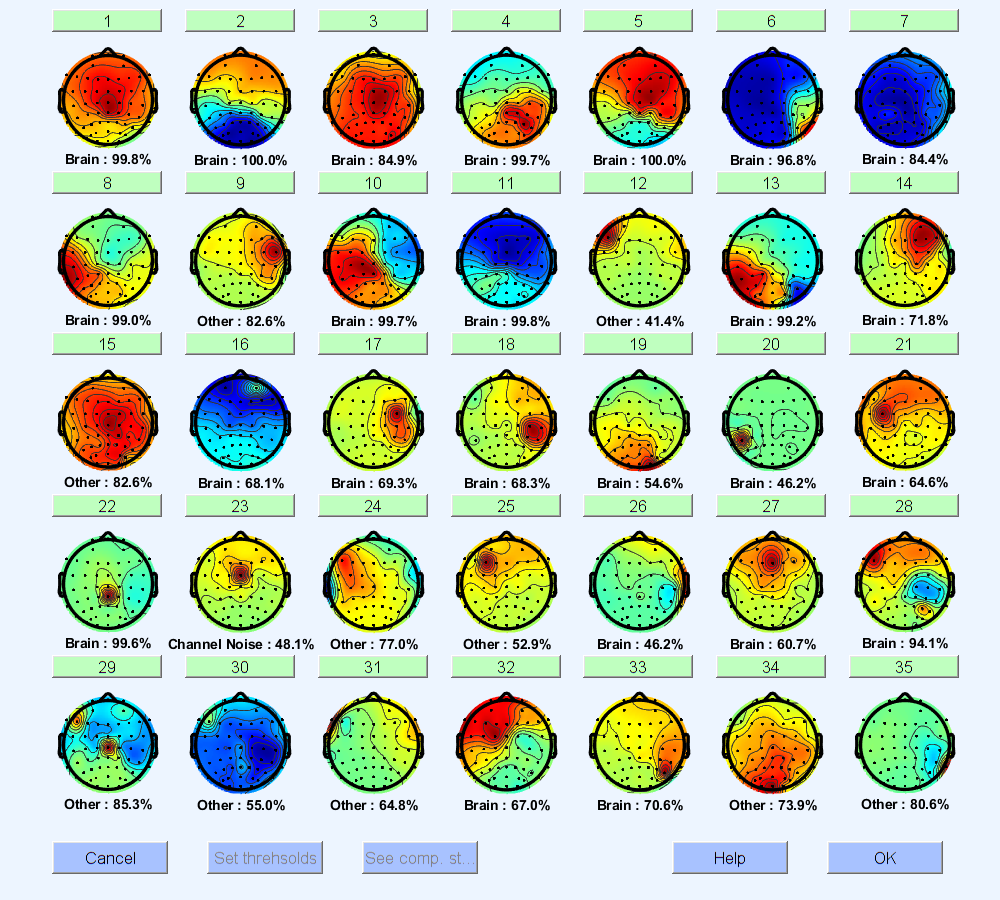

Drawing figure...


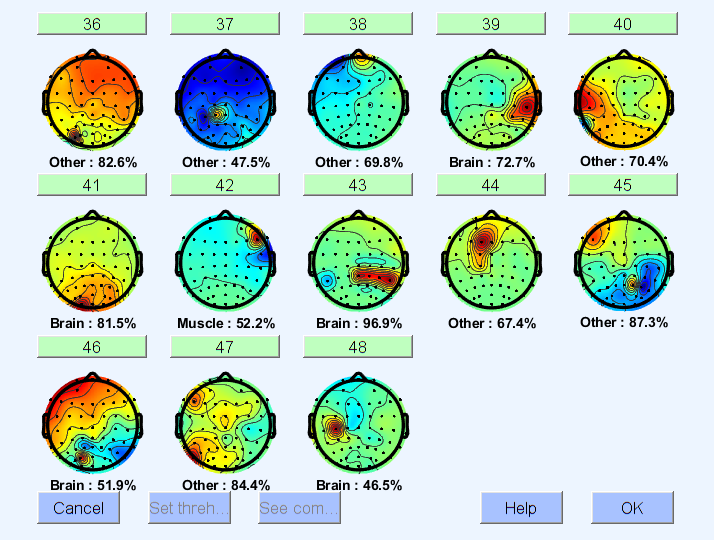


% Make sure EEG is loaded and checked
EEG = eeg_checkset(EEG);

% Check if ICA has been computed
if isfield(EEG, 'icaweights') && ~isempty(EEG.icaweights)
    nComps = size(EEG.icaweights, 1);
    fprintf('Number of ICA components: %d\n', nComps);
    
    pop_selectcomps(EEG, 1:nComps);
else
    error('EEG does not have ICA weights. Run ICA first using runica.');
end

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


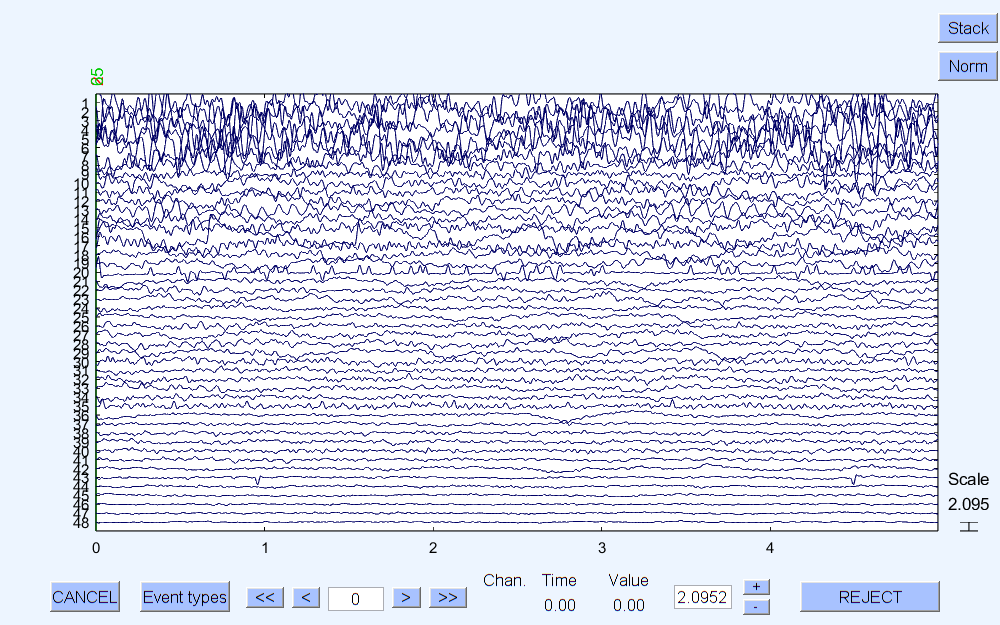


%7+ plot plot
pop_eegplot( EEG, 0, 1, 1);

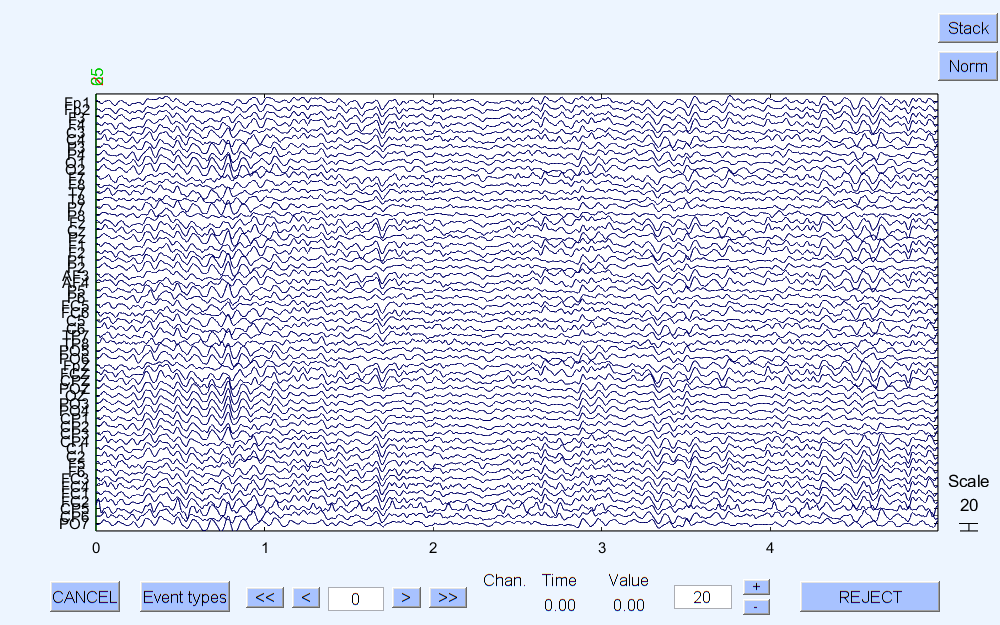



%plot plot plot
pop_eegplot(EEG, 1, 1, 1);



%8-------- shortest time---------------------------


% Current folder
currentFolder = pwd;

% Look for the cleaned EEG dataset
filePattern = fullfile(currentFolder, '*_cleaned_after_ica.set');
files = dir(filePattern);
% Full path to the file


% Load the EEG dataset
EEG = pop_loadset('filename', files(1).name, 'filepath', currentFolder);

pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\sub-CBM00281_cleaned_after_ica.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\sub-CBM00281_cleaned_after_ica.fdt'...



fprintf('Loaded EEG dataset: %s\n', files(1).name);

Loaded EEG dataset: sub-CBM00281_cleaned_after_ica.set



type = 65;         % code for "eyes closed"

% EEG.srate, EEG.event now available

%% Find all eye-closed event onsets
eveVals   = [EEG.event.type];    
eveSamps  = [EEG.event.latency];  
closedIdx = find(eveVals == type);
nTrials   = numel(closedIdx);

%%  Measure each segment’s length in samples
lengths = zeros(nTrials,1);
for k = 1:nTrials
    startS = eveSamps(closedIdx(k));
    if k < nTrials
        endS = eveSamps(closedIdx(k)+1) - 1;
    else
        endS = EEG.pnts;
    end
    lengths(k) = endS - startS + 1;
end

%%  Pick the shortest segment length
numSamples = min(lengths);
fprintf('Subject has %d eye-closed periods; shortest = %d samples.\n', ...
        nTrials, numSamples);

Subject has 16 eye-closed periods; shortest = 1860 samples.



%9--------------------------segment---------------------------
% CHANGE TIME POOOOIIIINNNTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTTT
%3 extract closed time
 [finalMatrix, extractedTrials, rejTimes, EEGclean] = finalextractEyeClosedTrials(EEG,65,1000);

eeg_insertbound(): 16 boundary (break) events added.
eeg_checkset note: event field format 'trial_type' made uniform


EEGclean = struct with fields:
             setname: 'sub-CBM00281_task-protmap_eeg pruned with ICA'
            filename: 'sub-CBM00281_cleaned_after_ica.set'
            filepath: 'C:\kar\matlab\subjects\Rahimi\Sub_281'
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Original file: C:\kar\matlab\subjects\Rahimi\Sub_281\sub-CBM00281_task-protmap_eeg.edf'
              nbchan: 57
              trials: 1
                pnts: 116976
               srate: 200
                xmin: 0
                xmax: 584.8774
               times: [0 5.0000 10.0000 15.0001 20.0001 25.0001 30.0001 35.0001 40.0002 45.0002 50.0002 55.0002 60.0002 65.0003 70.0003 75.0003 80.0003 85.0003 90.0004 95.0004 100.0004 105.0004 110.0004 115.0005 120.0005 125.0005 130.0005 135.0005 … ]
                data: [57×116976 single]
              icaact: []
             icawinv: [57×48 double]
           icasphere: [57×57 double]
          icawei

Removed 16 segments (total 584.8 s; min length 9.30 s)



%% Save the matrix automatically
matFilename = [subID, '_finalMatrix.mat'];
save(fullfile(pwd, matFilename), 'finalMatrix', 'extractedTrials', 'EEGclean');

fprintf('finalMatrix and related data saved to %s\n', matFilename);

finalMatrix and related data saved to sub-CBM00281_finalMatrix.mat


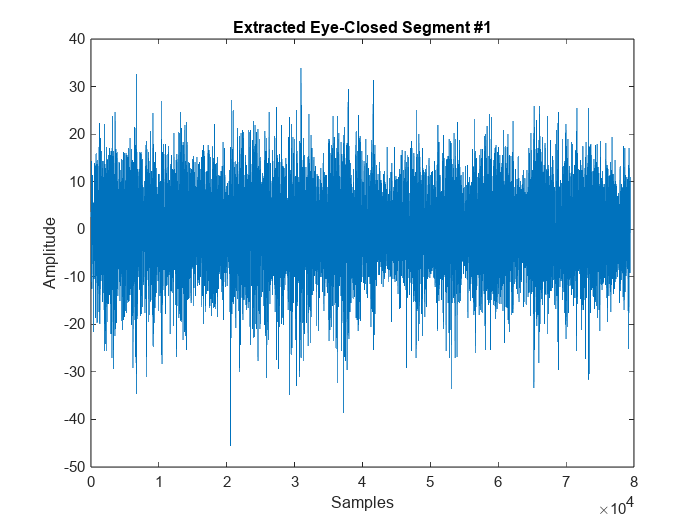

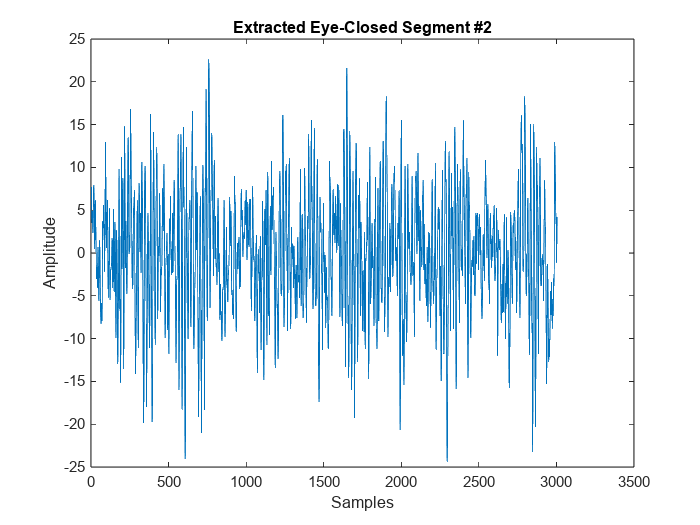

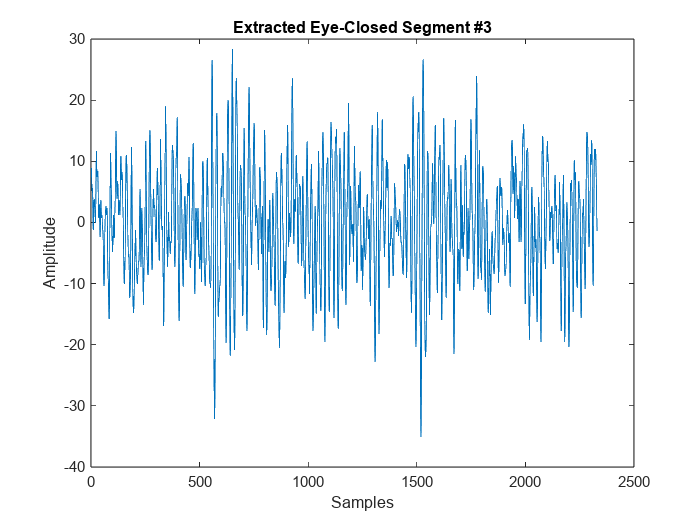

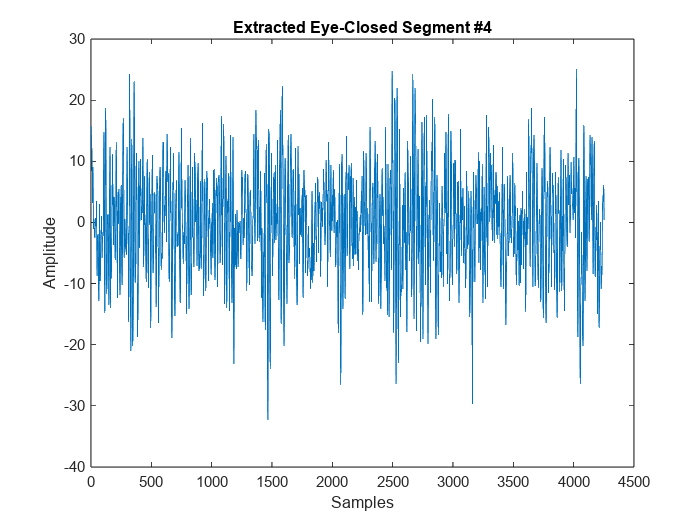

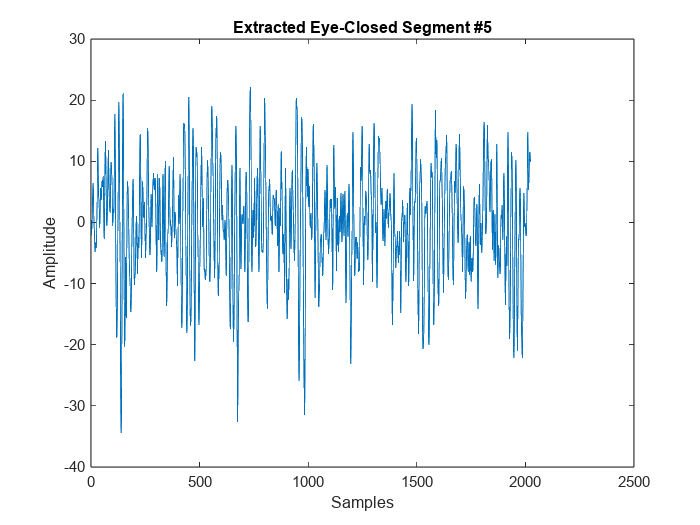

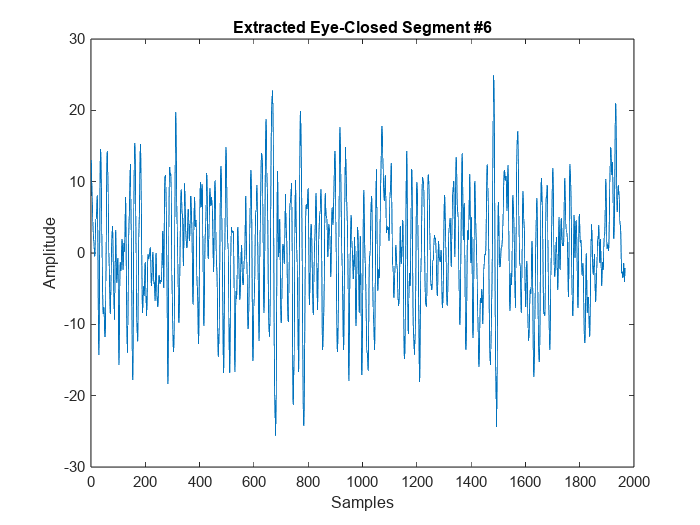

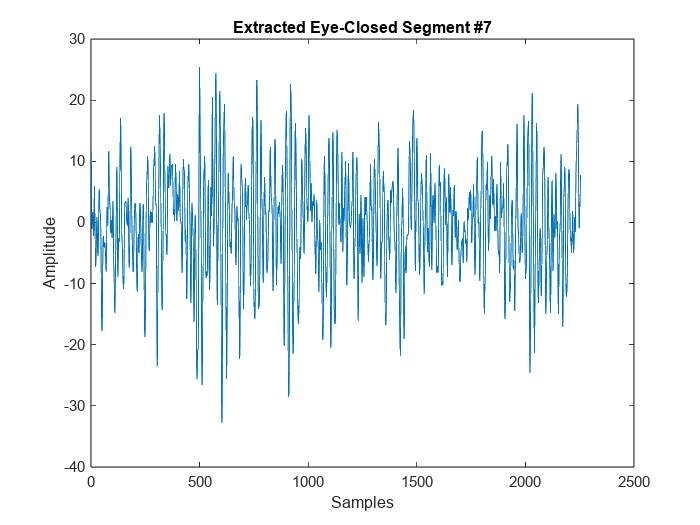

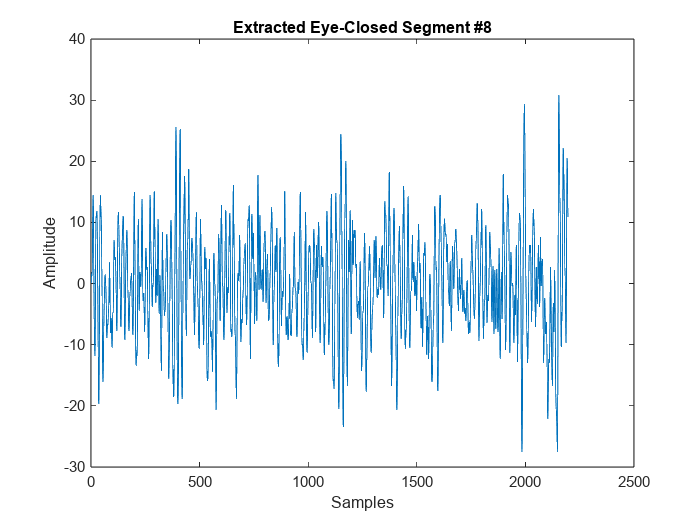




%----10----- plot

numTrials = length(extractedTrials);

for i = 1:numTrials
    figure;                         
    plot(extractedTrials{i}(1,:));    % Plot channel 1 (or choose another)
    xlabel('Samples');
    ylabel('Amplitude');
    title(['Extracted Eye-Closed Segment #' num2str(i)]);
end


%---------------------------------------------------------
% STEP 11: SAVE EACH SEGMENT SEPARATED in .set
% Assuming finalMatrix is already computed as [trials x chans x samples]
data_for_eeglab = permute(finalMatrix, [2 3 1]); % [channels x time x trials]

% Load cleaned channel locations (57 channels)
load('loc57.mat','loc57');
% Assign the 57-channel locations
EEG.chanlocs = loc57;

% Define output path for middle trials
outpath = pwd;

% Define subject ID
if isfield(EEG, 'subject')
    subID = EEG.subject;
else
    subID = 'unknown';
end

% Number of trials
nTrials = size(data_for_eeglab, 3);

% Loop to save middle trials (exclude first and last)
for t = 2:(nTrials-1)
    % Construct distinct filename with '.newset' suffix
    outname = [subID, '_trial', num2str(t), '.newset'];
    
    % Create a fresh empty EEG structure
    EEG_trial = eeg_emptyset();
    EEG_trial.data   = data_for_eeglab(:,:,t);
    EEG_trial.nbchan = size(EEG_trial.data, 1);  % should be 57
    EEG_trial.pnts   = size(EEG_trial.data, 2);
    EEG_trial.trials = 1;
    EEG_trial.srate  = 200;  % or your actual sampling rate
    EEG_trial.times  = (0:EEG_trial.pnts-1) * 1000 / EEG_trial.srate;
    
    % Assign channel locations
    EEG_trial.chanlocs = loc57;
    
    % Give the EEG set a name
    EEG_trial.setname = [subID, '_trial', num2str(t)];
    
    % Check consistency
    EEG_trial = eeg_checkset(EEG_trial);
    
    % Save the trial dataset
    pop_saveset(EEG_trial, 'filename', outname, 'filepath', outpath);
end

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving dataset...



disp(['Saved trials 2 to ' num2str(nTrials-1) ' to folder ' outpath]);

Saved trials 2 to 15 to folder C:\kar\matlab\subjects\Rahimi\Sub_281


%save middle matrix
middleMatrix = finalMatrix(2:end-1, :, :);
data_for_eeglab = permute(middleMatrix, [2 3 1]);  % channels x samples x trials
subID = EEG.subject;
matFilename = [subID '_middle_matrix.mat'];
save(fullfile(pwd, matFilename), 'middleMatrix', 'extractedTrials', 'EEGclean');
numTrials = size(middleMatrix, 1);
fprintf('Number of trials in middleMatrix: %d\n', numTrials);

Number of trials in middleMatrix: 14



% STEP 12: LOAD SEGMENTS & BUILD ERP-STYLE DATASET
%---------------------------------------------------------


% Use current folder for input and output
dataFolder = pwd;
outFolder  = pwd;


% Load all segmented .set files
setFiles = dir(fullfile(dataFolder, '_trial*.set'));
nTrials = numel(setFiles);

% Preload one to get dimensions
tmpEEG = pop_loadset('filename', setFiles(1).name, 'filepath', dataFolder);

pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial10.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial10.fdt'...


nChan  = tmpEEG.nbchan;
nTime  = tmpEEG.pnts;
srate  = tmpEEG.srate;

% Preallocate ERP-style data: [chan x time x trials]
merged_data = zeros(nChan, nTime, nTrials);

% Load data from each trial
for i = 1:nTrials
    EEG = pop_loadset('filename', setFiles(i).name, 'filepath', dataFolder);
    merged_data(:,:,i) = EEG.data(:,1:nTime);
end

pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial10.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial10.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial11.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial11.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial12.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial12.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial13.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial13.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial14.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial14.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\Rahimi\Sub_281\_trial15.set ...
Reading float file 'C:\kar\matlab\subjects\Rahimi\Sub_281\_trial15.fdt'...
pop_loadset(): loading file C:\kar\matlab\subjects\R


% Create ERP-style EEG struct
EEG = eeg_emptyset();
EEG.data     = merged_data;
EEG.nbchan   = nChan;
EEG.pnts     = nTime;
EEG.trials   = nTrials;
EEG.srate    = srate;
EEG.times    = (0:nTime-1) * 1000 / srate;

% ✅ Assign correct 57-channel locations
load('loc57.mat', 'loc57');
EEG.chanlocs = loc57;

%CHANGEEEEEEEEEEEEEEEEE NAMEEEEEEEEEEEEEEEEEEEEEEE

% Set name & save
EEG.setname = '_ClosedEye_ERPStyle_middleONES_';
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


%CHANGEEEEEEEEEEEEEEEEE NAMEEEEEEEEEEEEEEEEEEEEEEE

pop_saveset(EEG, ...
'filename', 'ClosedEye_ERPStyle_step12.set', ...
'filepath', outFolder);

Saving dataset...


%CHANGEEEEEEEEEEEEEEEEE NAMEEEEEEEEEEEEEEEEEEEEEEE
disp('✅ Step 12 done: ERP-style EEG with 57 channels saved.');

✅ Step 12 done: ERP-style EEG with 57 channels saved.


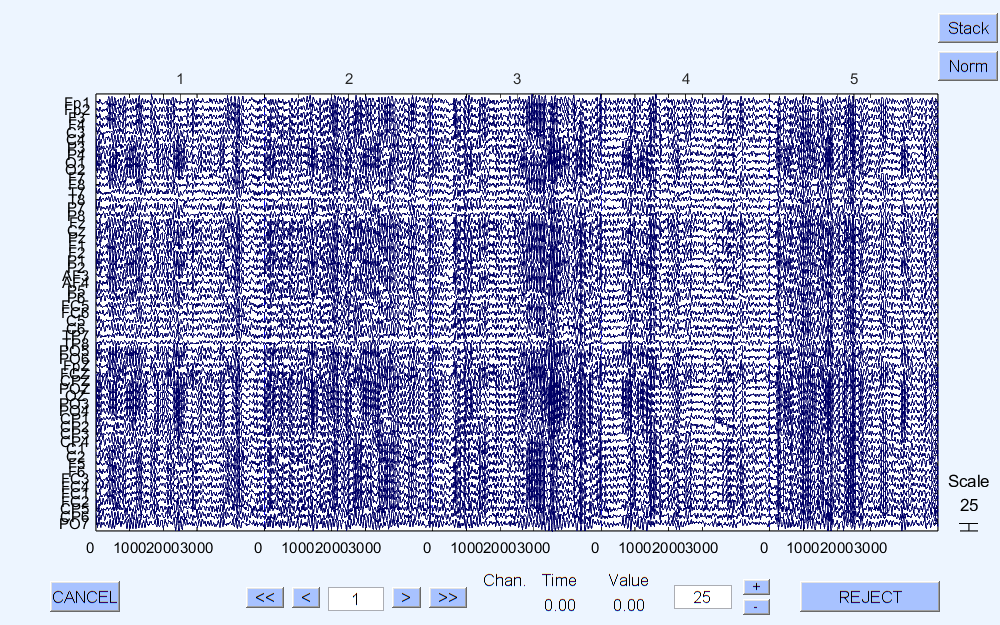


% Optional: Plot for visual check
pop_eegplot(EEG, 1, 1, 1);